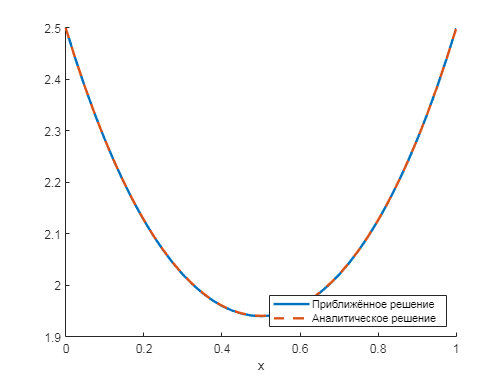

clear all
syms x t s tau

h = 0.025;
tay = h;

m = 1 / h;
l = m;

T = 0:tay:1;
X = 0:h:1;

N = 5; n = 62;
beta = N / 2;
alpha = 64 - n;
D = 1;

f(t, x) = -2*beta + alpha * beta * pi * (x - x^2) / 2 * cos(pi/2 * t) - 2*alpha * beta * sin(pi/2 * t)

p = D * tay / h^2;
q = 1 - 2*p;
r = p;

G = zeros(m+1);

for i = 2:m
    
    G(i, i - 1) = p;
    G(i, i) = q;
    G(i, i + 1) = r;

end


Mu = zeros(m + 1, 1);
for i = 1:m+1
    Mu(i) = 2*beta;
end

Beta = zeros(m + 1, l + 1);
F = zeros(m + 1, l + 1);
for j = 1:l+1
    Beta(1, j) = 2*beta*(1 - T(j));
    Beta(m + 1, j) = 2*beta*(1 - T(j));
    F(:, j) = f(T(j), X);
    F(1, j) = 0;
    F(m + 1, j) = 0;
end

U_1 = zeros(m + 1, l + 1);
U_1(:, 1) = Mu;

for i = 2:l + 1
    U_1(:, i) = G * U_1(:, i - 1) + Beta(:, i) + tay * F(:, i - 1);
end

p = -D * tay / h^2;
q = 1 - 2*p;
r = p;

H = zeros(m+1);
H(1, 1) = 1;
H(m + 1, m + 1) = 1;
for i = 2:m
    
    H(i, i - 1) = p;
    H(i, i) = q;
    H(i, i + 1) = r;

end

U_2 = zeros(m + 1, l + 1);
U_2(:, 1) = Mu;

for i = 2:l+1
    
    L = zeros(m + 1, 1);
    M = zeros(m + 1, 1);
    R = U_2(:, i - 1) - Beta(:, i - 1) + Beta(:, i) +  tay * F(:, i);

    L(1) = -H(1, 2)/H(1, 1);
    M(1) = R(1)/H(1, 1);
    for j = 2:m
        L(j) = -H(j, j + 1)/(L(j-1) * H(j, j - 1) + H(j, j));
        M(j) = (R(j) - M(j - 1) * H(j, j - 1))/(L(j - 1) * H(j, j - 1) + H(j, j));
    end
    L(m+1) = 0;
    M(m+1) = (R(m+1) - M(m) * H(m+1, m))/(L(m) * H(m+1, m) + H(m+1, m+1));

    U_2(m + 1, i) = M(m + 1);
    for j = fliplr(1:m)
       U_2(j, i) = L(j) * U_2(j + 1, i) + M(j); 
    end

end

for i = 2:l + 1
    U_2(:, i) = inv(H) * (U_2(:, i - 1) - Beta(:, i - 1) + Beta(:, i) +  tay * F(:, i));
end

writematrix(G, "D:\Study\МГТУ\ЛБ_ОСМ\ЛБ_ОСМ№4.xlsx", 'Sheet', 5);

% Функция Грина
clear G
G(x, s, t) = 0*x*s*t;

k = 100;
for i = 1:k
    
    G(x, s, t) = G(x, s, t) + 2 * sin(i * pi * x) * sin(i * pi * s) * exp(-(i * pi )^2 * t);

end

f_1(t, x) = -4*alpha * beta * sin(pi/2 * t);
u(t,x) = int(int(G(x, s, t - tau) * f_1(tau, s), s, 0, 1), tau, 0, t);

u(t,x) = u(t, x) + 2*beta*(1 - t) + alpha * beta * (x - x^2) * sin(pi/2*t);

plot(X, U_2(:, 21), 'Linewidth', 2)
hold on
fp = fplot(u(0.5,x), [0, 1], 'Linewidth', 2);
fp.LineStyle = '--';
legend("Приближённое решение", "Аналитическое решение");
xlabel("x");
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');
legend('Location', 'southeast')
box off
hold off

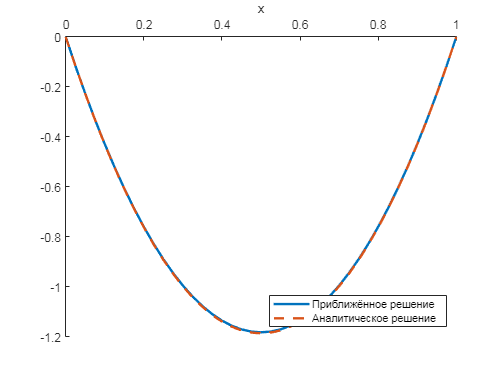


plot(X, U_2(:, 41), 'Linewidth', 2)
hold on
fp = fplot(u(1,x), [0, 1], 'Linewidth', 2);
fp.LineStyle = '--';
legend("Приближённое решение", "Аналитическое решение");
xlabel("x");
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');
legend('Location', 'southeast')
box off
hold off

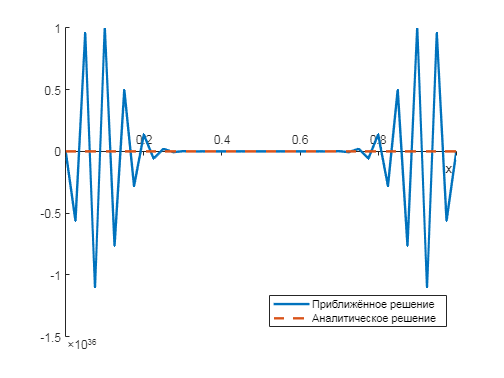


plot(X, U_1(:, 21), 'Linewidth', 2)
hold on
fp = fplot(u(0.5,x), [0, 1], 'Linewidth', 2);
fp.LineStyle = '--';
legend("Приближённое решение", "Аналитическое решение");
xlabel("x");
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');
legend('Location', 'southeast')
box off
hold off

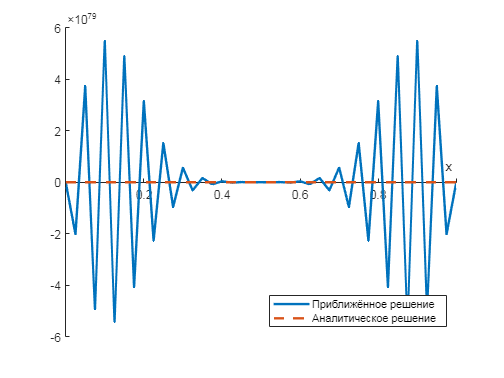


plot(X, U_1(:, 41), 'Linewidth', 2)
hold on
fp = fplot(u(1,x), [0, 1], 'Linewidth', 2);
fp.LineStyle = '--';
legend("Приближённое решение", "Аналитическое решение");
xlabel("x");
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');
legend('Location', 'southeast')
box off
hold off


A = zeros(m + 1, m + 1);

for i = 1:m + 1
    for j = 1:m + 1
        
        A(i, j) = u(T(j), X(i));

    end
end

norm(abs(U_1 - A), 1)

ans = 7.9300e+80

norm(abs(U_2 - A), 1)

ans = 0.4317